# Exercise 2

## Using an Extended Kalman Filter for a Differential Drive Robot

### About This Exercise

The Kalman filter is very powerful for linear systems as it gives the most likely estimate of the state variables given additive Gaussian process and measurement noise. However, given that most physical systems are non-linear, including our differential drive robot, can we still apply the Kalman filter? The answer is ***yes***, because just as any curve looks linear around a zoomed in point, we can approximate the kinematics of our nonlinear system as linear around the estimate of the state.

What does this linearization process change for our Kalman filter? Not too much actually. We still have two steps, the prediction step and the update steps. However, one of the key changes to these steps is the need to calculate the **Jacobian** matrix of both the kinematic equations and the observation equations. These Jacobians contain the partial derivative of those equations with respect to each state variable. These partial derivatives are like calculating the slope of a curve at a point, only in higher dimensions, where the curve becomes a surface and there are slopes in multiple directions. In this exercise, we will go through the steps to write functions to calculate the Jacobians and implement them with the extended Kalman filter with the differential drive robot.  

**By the end of this exercise, you'll be able to: **

- **Write functions to calculate Jacobians of kinematic and observation equations.**

- **Implement the extended Kalman filter with a differential drive robot.**

*Remember to connect with your peers and the course facilitator if you get stuck or need help working through any part of this exercise.*

### The Process Jacobian

The Jacobian is simply a matrix of all the partial derivatives of equations with respect to all of the variables in the equations. For us, we calculate the Jacobians of the kinematic and observation equations with respect to the 3 states (the three components of the pose, $x,y$ and $\theta$). When the Jacobian is evaluated for a particular pose, the result is a matrix of values similar to the A and C matrices for the linear system in that they contain constant values and are used the same in the Kalman filter prediction and update equations. 

#### Linear Kinematics

- Initialize states and control inputs

x_start = 0;
y_start = 0;
Vx = 1;
Vy = 1;
dt = 0.01;

- The following are the kinematic equations for the holonomic robot: 

x_next = x_start + Vx*dt;
y_next = y_start + Vy*dt;

- Using the equations above, fill out the partial derivatives below. As the equations are linear the partial derivatives should all be constants.

**Complete the code below.**

dxdx = 1; 
dxdy = 0; 
dydx = 0; 
dydy = 1; 

- Assemble the partial derivates into the Jacobian matrix G.

G = [dxdx, dxdy; ...
     dydx, dydy]

G =      1     0
     0     1


- Remember that the matrix G is the EKF version of the matrix A from the KF. Therefore, for a linear system, G and A are exactly the same.

#### Differential Drive Kinematics

- Initialize states and control inputs

x_start = 0;
y_start = 0;
theta_start = 0; % change value here (0-2pi)
V = 2;
omega = 1;

- Kinematic equations 

x_next = x_start + V*cos(theta_start)*dt;
y_next = y_start + V*sin(theta_start)*dt;
theta_next = theta_start + omega*dt;
pose_next = [x_next,y_next,theta_next]'

pose_next =     0.0200
         0
    0.0100


- Using the equations above, fill out the partial derivatives below. Now some terms will depend on the current state (specifically theta)

**Complete the code below.**

dxdx = 1; 
dxdy = 0; 
dxdth = -V*sin(theta_start)*dt; 

dydx = 0; 
dydy = 1; 
dydth = V*cos(theta_start)*dt; 

dthdx = 0; 
dthdy = 0; 
dthdth = 1; 

- G (the Jacobian of the kinematic equations) is dependent on theta_start therefore it is non-linear as expected.

**Complete the code below:**

G = [dxdx, dxdy, dxdth; ...
     dydx, dydy, dydth; ...
     dthdx, dthdy, dthdth]

G =     1.0000         0         0
         0    1.0000    0.0200
         0         0    1.0000


- The matrix G contains the partial derivatives evaluated at the current pose as we are linearizing around the current pose (or guess of what the pose is). Changing the slider above for theta_start shows how this matrix changes with theta.

Lets put the above into a function called procFunc that will return both the integrated state from the kinematic equations as well as the Jacobian matrix G evaluated at the current pose.

[► Complete the procFunc function](matlab:open('./procFunc.mlx')) 

Test with the following, the results should match the output above 

u = [1,1]; % current control input [V omega]
[pose_next,G] = procFunc([x_start,y_start,theta_start], u, dt)

pose_next =     0.0100
         0
    0.0100


G =     1.0000         0         0
         0    1.0000    0.0100
         0         0    1.0000


## Jacobian of measurement model

We need one more Jacobian matrix (which we call H) to replace our observation matrix C, which assumed a linear relationship between the measurements and the states. Now that we have the robot orientation angle as a state, that relationship may involve non-linear sinusoidal functions. Actually, our previous observation function had a non-linearity that we conveniently ignored. Do you know what it was?

For this exercise, we will implement a noisy GPS sensor, which is actually linear because it directly provides the position. In the next exercise, we will create functions to linearize both the lidar range sensor and a beacon sensor. However, the form of the function we create for the GPS sensor will be the same as that for the others. It will return both the expected measurement and the Jacobian matrix H given the pose and other necessary inputs

[► Complete the measFuncGPS function](matlab:open('./measFuncGPS.mlx'))

Once the function is complete, test it with the following:

- Initialize the input variable, as other sensors will have different input arguments, we will put them all into a single struct called args.

robotPose = [1.25 1 0]';
args.robotPose = robotPose;

- Use your function to get the expected measurement and matrix H

[expected, H] = measFuncGPS(args)

expected =     1.2500
    1.0000


H =      1     0     0
     0     1     0


### EKF Inputs

We now have all of the necessary inputs for the extended Kalman filter. We'll put them all together into a MATLAB struct called ekfArg that holds all the information need to solve an EKF timestep.

ekfArgs.map = load('MAP102.txt');

- Starting guess,  covariance, and timestep 

ekfArgs.mu = [-1.25;1;-pi/2];
sigma_value = .5; % change value here
ekfArgs.sigma = sigma_value*eye(3);
ekfArgs.dt = .1;

- Process and Measurement covariance matrices R and Q

Q_value = .1; % change value here
ekfArgs.Q = Q_value*eye(2);
R_value = .02; % change value here
ekfArgs.R = diag([R_value R_value R_value]);

- Function handles to the process function and measurement function. These are the functions you created in the previous exercise and will be called within the EKF function. The @ symbol indicates a handle to a function, which can be used in the MATLAB *feval* function as well as others.

ekfArgs.procFunc = @procFunc;
ekfArgs.measFunc = @measFuncGPS;

- Current control input and measurement, these will change every timestep 

ekfArgs.u = [0;0]; % control is [V; omega];
ekfArgs.measurement = robotPose(1:2);

#### EKF Function

Now that we have organized all of the inputs to the EKF function into a single MATLAB struct, we can now develop the EKF function itself. Similar to the KF function, it performs one iteration of the EKF algorithm and returns the updated $\mu$ and $\Sigma$ given the current control inputs, measurement, and all other parameters above.

[► Complete the EKF function](matlab:open('./EKF.mlx'))

Once it is finished, test it with the following.

[mu, sigma] = EKF(ekfArgs)

mu =     0.8468
    1.0000
   -1.5708


sigma =     0.0839         0         0
         0    0.0839         0
         0         0    0.5200


### Simulate an Arc Trajectory

We need to simulate a trajectory for the differential drive robot to test our EKF. A perfect candidate trajectory is the simple arc trajectory from MAE101 that uses a constant forward and rotational velocity as the inputs. Use your findArcPath to find $V$, $\omega$, and the time needed to get from starting pose $[1.25,0.5,-\pi/2]$ to point $[-1.25,-0.4]$.

- Wheel limit parameter

maxWheelSpeed = 10;

- Starting Pose and Goal point

robotPose = [1.25;0.5;-pi/2];
goal_xy = [-1.25; -.4];

- The following uses your previous findArcPath code and generates and then plots the non-noisy and noisy trajectories.

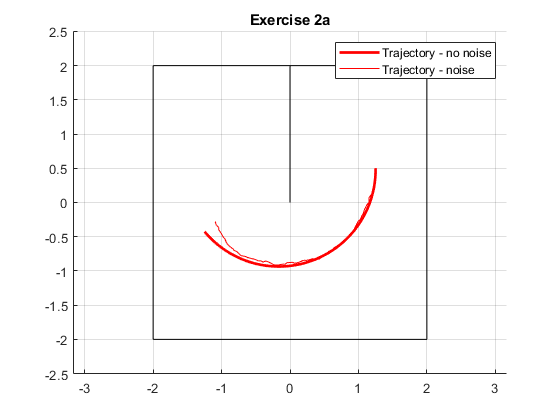

[u, robotXYtraj, robotXYtrajNoisy, measurements] = simulateArc(robotPose, goal_xy, maxWheelSpeed, ekfArgs);
plot_title = "Exercise 2a"; 
external_figure = 1; % you can choose "1" to have an external figure or "0" to turn this feature off.
plotTraj(ekfArgs.map, robotXYtraj, robotXYtrajNoisy, plot_title, external_figure); 

## EKF loop

implement the EKF function in the loop that goes through each control step. You'll need to update the current control vector and current measurement into the struct that is input into EKF. The outputs of EKF will update the current estimate for $\mu$ and covariance $\Sigma$, which will be used for the next step. We will store the outputs for each iteration for plotting.

- Store initial guess. Here is where you can test out the sensitivity of the EKF to how good your initial guess is. Start with an orientation matching the true orientation and later see how far away you can get before the localization fails.

ekfArgs.mu = [1.25;1;-pi/2];
ekfArgs.sigma = .5*eye(3);

- Initialize matrix to store predicted states mu 

mu_hist = zeros(3,1+length(u));
sigma_hist = zeros(3,3,1+length(u));
mu_hist(:,1) = ekfArgs.mu;
sigma_hist(:,:,1) = ekfArgs.sigma;

- Loop through control inputs

for i = 1:length(u)
    %Set current control input
    ekfArgs.u = u(:,i);

    %Set current 'true' measurement
    ekfArgs.measurement = measurements(:,i);
    
    %Get next guess mu and covariance sigma using EKF
    [ekfArgs.mu,ekfArgs.sigma] = EKF(ekfArgs);
    
    %Store guess for plotting
    mu_hist(:,i+1) = ekfArgs.mu;
    sigma_hist(:,:,i+1) = ekfArgs.sigma;
end

Plot the result

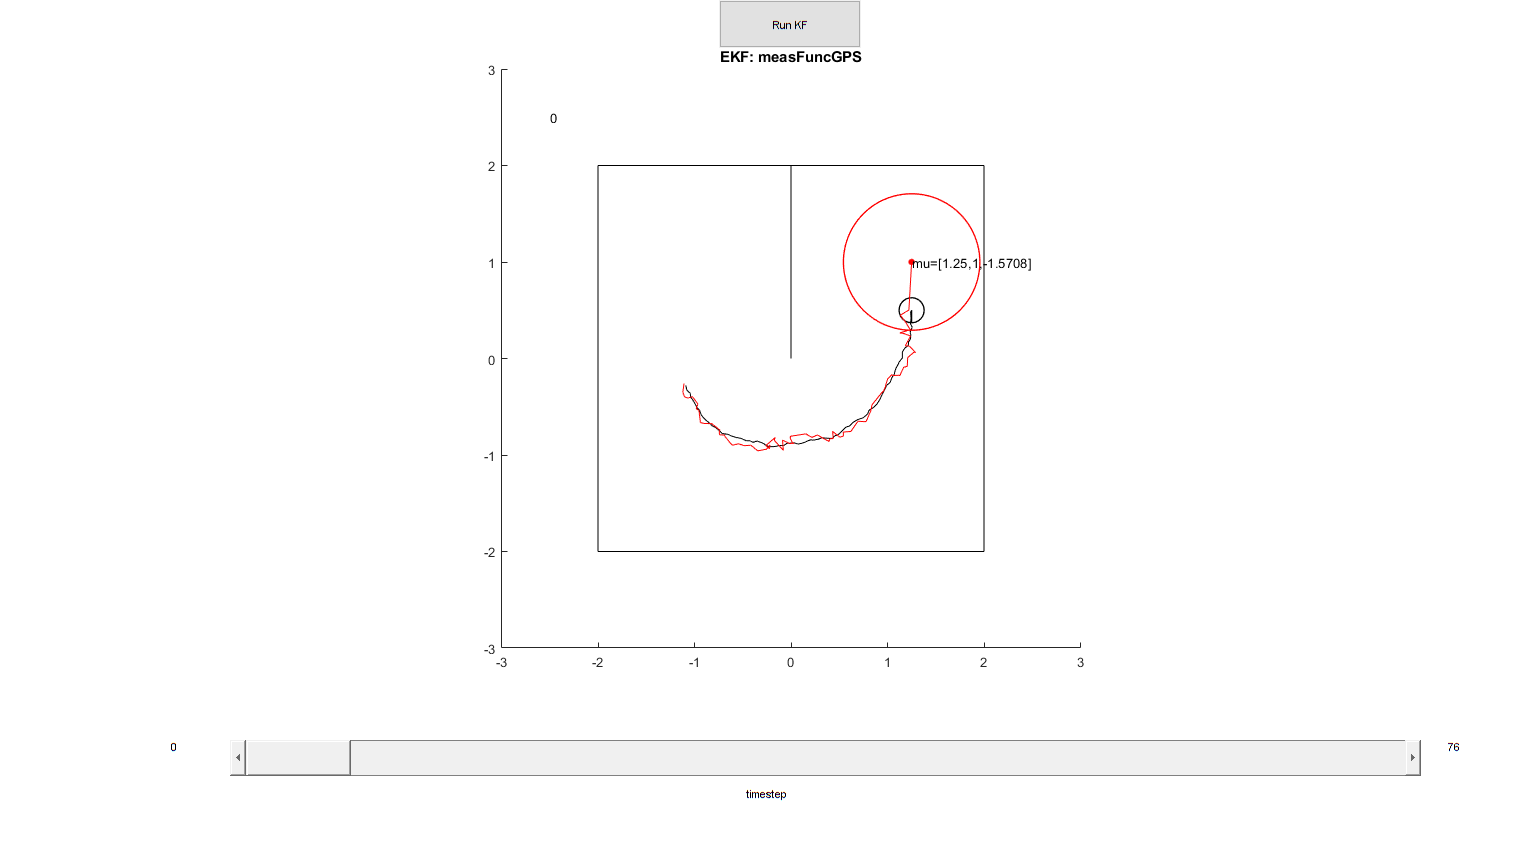

plotKF(mu_hist,sigma_hist,robotXYtrajNoisy,ekfArgs.map, ekfArgs.measFunc)

You'll notice that the initial estimate given in the starter code is pretty close to the actual initial pose. Try changing the position and orientation to see how the initial guess affects the localization using the EKF. Which state is most sensitive to changes? Why do you think this is?

### Finished!

You can now localize the differential drive robot using the extended Kalman filter. Not only that, but you have created a general EKF function that could use any nonlinear robot and any expected measurement function. In the project, we will use the EKF in the simulator to try the same task from before but without the overhead sensor that gave us the actual pose at all times.